# BME3053C Homework 10

% BME 3053C Homework 10 

%

% Author: Maria Serafim

% Group Members: Maria C Gomes, Gabriel Veliz

% Course: BME 3053C Computer Applications for BME

% Term: Fall 2020

% J. Crayton Pruitt Family Department of Biomedical Engineering

% University of Florida

% Email: mserafim@ufl.edu

% November 13th, 2021

% BME 3053C Homework 10
%
% Author: Maria Serafim
% Group Members: Maria C Gomes, Gabriel Veliz
% Course: BME 3053C Computer Applications for BME
% Term: Fall 2020
% J. Crayton Pruitt Family Department of Biomedical Engineering
% University of Florida
% Email: mserafim@ufl.edu
% November 13th, 2021

**Step 1 (1 point):  **Read the image “paramecium.jpg” and save it to a variable `I`. (~1 line)

I = imread('Paramecium.jpg');

**Step 2 (1 point): **Convert the image from RGB to gray-scale and still save in the varible `I`. (~1 line)

I = rgb2gray(I);

**Step 3 (1 point): **Apply the sobel edge detection using `edge` function and get the edge detection threshold as the 2nd output variable. Save it in a variable called thresh. (~1 line)

[~,thresh] = edge(I,'Sobel');

**Step 4 (1 point)** Assign the **fudgeFactor **variable with a value 0.8 (~1 line) 

fudgeFactor = 0.8;

**Step 5 (2 points): **Detect the edge of `I` again using "Sobel" filter by applying a threshold which is** fudgeFactor * thresh **and perform edge detection (~1 line) 

Iedge = edge(I,'Sobel', fudgeFactor*thresh);

**Step 5 (1 point): Show i**mage `Iedge` (~1 line)

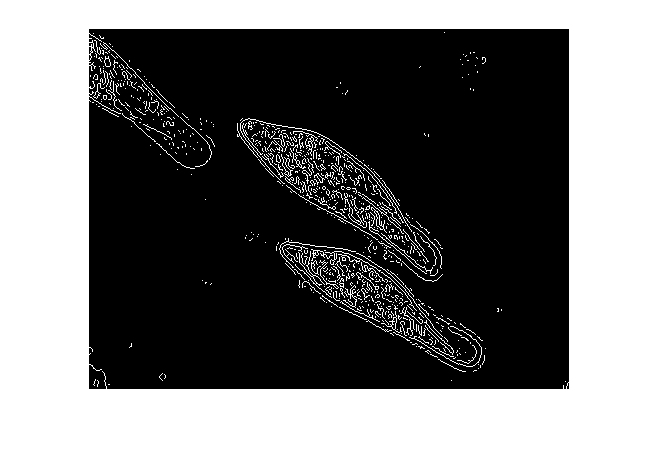

imshow(Iedge);

**Step 6 (2 points): ** Now we want to dilate the image, so first create two linear structuring elements** se90 **and **se0 **whose length are 3, and angles are 90 degree and 0 degree respectively (~2 lines)

se90 = strel('line',3,90);
se0 = strel('line',3,0);

**Step 7 (1 point): **Dilate `Iedge` by applying both structural elements sec90 and sec0 at the same time and create a new image `Idilate` (~1 line)

Idilate = imdilate(Iedge,[se90,se0]);

**Step 8 (1 point): **Show `Idilate `and add a title ('Dilated Image') (~2 lines)

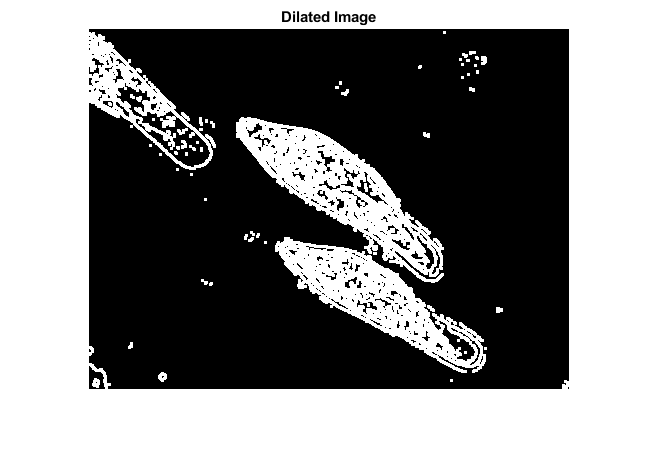

imshow(Idilate);
title('Dilated Image');

**Step 9 (1 point): **Fill the interior holes of `Idilate` to create a new image `Ifill `(~1 line)

Ifill = imfill(Idilate,'holes');

**Step 10 (1 point): **  Show image `Ifill` and add a title "Binary Image with holes filled" (~2 lines)

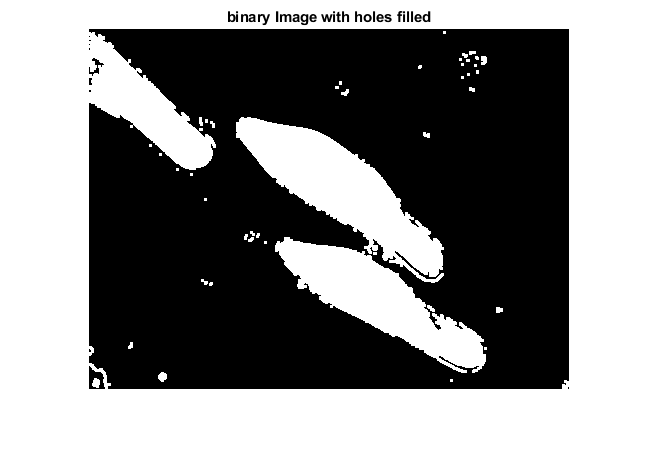

imshow(Ifill);
title('binary Image with holes filled');

**Step 11 (1 point): **Remove the connected objects creating `Iclear` image using 4-connected neighbors (~1 line)

Iclear = imclearborder(Ifill, 4);

**Step 12 (1 point):** Show `Iclear` and add a title 'Cleared border image' (~2 lines)

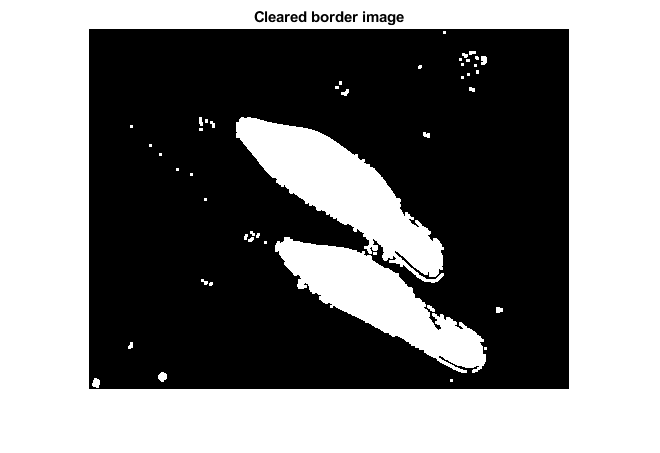

imshow(Iclear);
title('Cleared border image');

**Step 13 (1 point): **Define a diamond shaped structural element** seD** using function **strel **with a distance of 1 between the orgin and the points on the boundary (~1 line)

seD = strel('diamond',1);

**Step 14 (2 points): **Smooth the image using `Imerode` function twice creating `Ifinal` image (~2 lines)

Ifinal = imerode(Iclear, seD);
Ifinal = imerode(Ifinal, seD);

**Step 15 ( 1 point): **Show image Ifinal and add a title "Segmented Image" (~2 lines) 

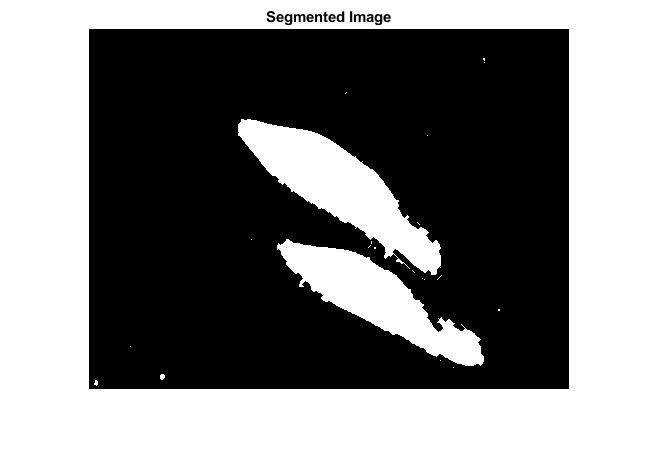

imshow(Ifinal);
title('Segmented Image');

**Step 16 (1 point): **Visualize the segmentation using **labeloverlay** function and add the title **"**Mask Over Original Image" (~2 lines)

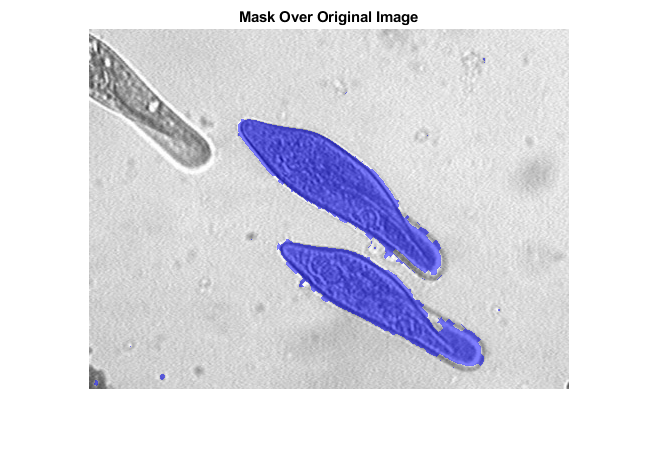

imshow(labeloverlay(I,Ifinal));
title('Mask Over Original Image');

## What to submit for this Question?

- H10.mlx